[y1, fs1] = audioread('s1.wav')

y1 =    -0.0015
   -0.0015
   -0.0015
   -0.0010
   -0.0010
   -0.0010
   -0.0010
   -0.0015
   -0.0020
   -0.0015


fs1 = 8000

[y2, fs2] = audioread('s2.wav')

y2 =          0
   -0.0003
    0.0000
   -0.0002
    0.0000
   -0.0002
   -0.0006
   -0.0007
   -0.0011
   -0.0006


fs2 = 8000

[y3, fs3] = audioread('s3.wav')

y3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs3 = 8000

[y4, fs4] = audioread('s4.wav')

y4 =    -0.0024
    0.0068
    0.0112
    0.0132
    0.0249
    0.0224
    0.0283
    0.0283
    0.0249
    0.0273


fs4 = 8000

[y5, fs5] = audioread('s5.wav')

y5 =    -0.0041
   -0.0051
   -0.0031
   -0.0026
   -0.0010
   -0.0010
   -0.0010
   -0.0010
         0
    0.0010


fs5 = 8000

[y6, fs6] = audioread('s6.wav')

y6 =    -0.0042
   -0.0016
   -0.0031
   -0.0010
   -0.0031
   -0.0031
   -0.0031
   -0.0031
   -0.0026
   -0.0026


fs6 = 8000

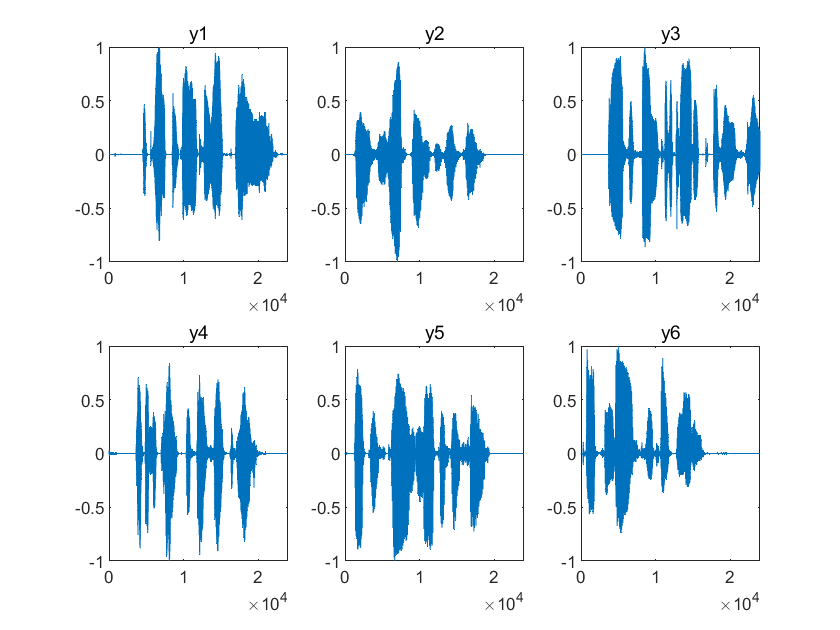


figure
subplot(231)
plot(y1), title('y1')
subplot(232)
plot(y2), title('y2')
subplot(233)
plot(y3), title('y3')
subplot(234)
plot(y4), title('y4')
subplot(235)
plot(y5), title('y5')
subplot(236)
plot(y6), title('y6')


y1_cut = y1(4535:23773);
y2_cut = y2(1071:18700);
y3_cut = y3(3687:end);
y4_cut = y4(3589:21510);
y6_cut = y6(261:16570);
y5_cut = y5(1265:19390);

y1_6 = vertcat(y1_cut, y2_cut, y3_cut, y4_cut, y5_cut, y6_cut);
y_male = vertcat(y2_cut, y4_cut, y4_cut, y5_cut, y6_cut);
y_female = vertcat(y1_cut, y2_cut);

audiowrite('out_s1_s6.wav', y1_6, fs2);
audiowrite('out_male.wav', y_male, fs1);
audiowrite('out_female.wav', y_female, fs1);

[y1, fs1] = audioread('out_s1_s6.wav');
[y2, fs2] = audioread('out_male.wav');
[y3, fs3] = audioread('out_female.wav');
% value config
mean1 = mean(y1)

mean1 = 1.5621e-04

var1 = var(y1)

var1 = 0.0323

max1 = max(y1)

max1 = 1.0000

min1 = min(y1)

min1 = -1.0000


mean2 = mean(y2)

mean2 = 1.6033e-04

var2 = var(y2)

var2 = 0.0291

max2 = max(y2)

max2 = 1.0000

min2 = min(y2)

min2 = -1.0000


mean3 = mean(y3)

mean3 = 1.4438e-04

var3 = var(y3)

var3 = 0.0273

max3 = max(y3)

max3 = 1.0000

min3 = min(y3)

min3 = -1.0000

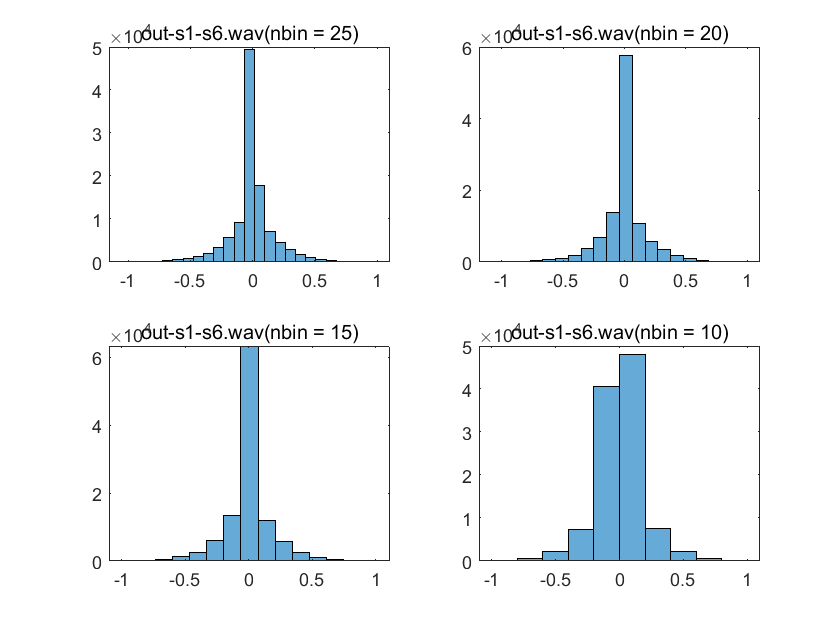


% histogram
figure
subplot(221)
histogram(y1, 25), title("out-s1-s6.wav(nbin = 25)")
subplot(222)
histogram(y1, 20), title("out-s1-s6.wav(nbin = 20)")
subplot(223)
histogram(y1, 15), title("out-s1-s6.wav(nbin = 15)")
subplot(224)
histogram(y1, 10), title("out-s1-s6.wav(nbin = 10)")
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab9/P1_a_1.png", 'png')

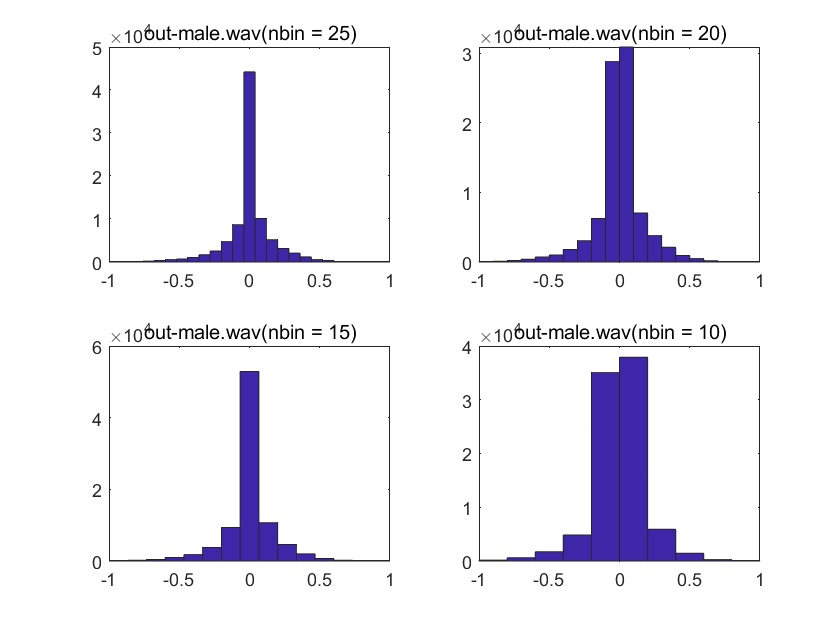


figure
subplot(221)
hist(y2, 25), title('out-male.wav(nbin = 25)')
subplot(222)
hist(y2, 20), title('out-male.wav(nbin = 20)')
subplot(223)
hist(y2, 15), title('out-male.wav(nbin = 15)')
subplot(224)
hist(y2, 10), title('out-male.wav(nbin = 10)')
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab9/P1_a_2.png", 'png')

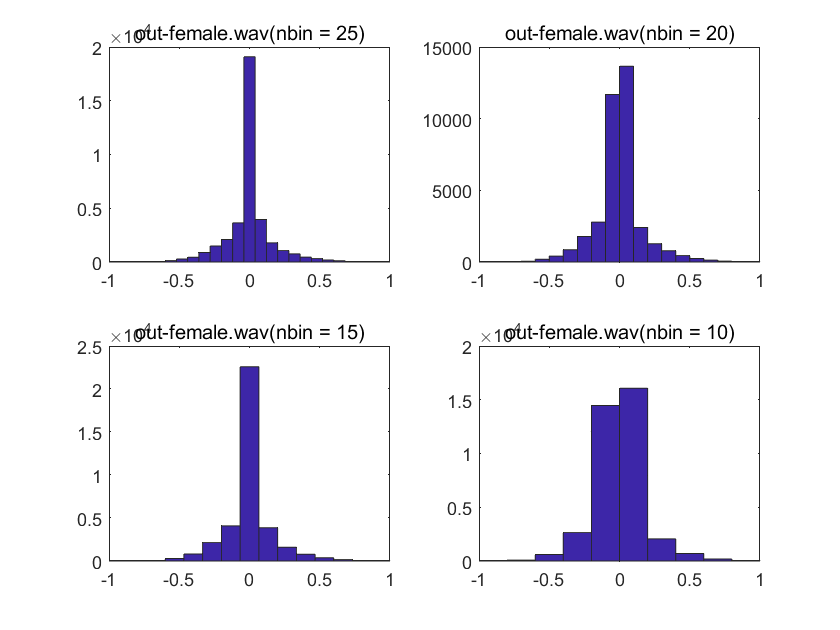


figure
subplot(221)
hist(y3, 25), title('out-female.wav(nbin = 25)')
subplot(222)
hist(y3, 20), title('out-female.wav(nbin = 20)')
subplot(223)
hist(y3, 15), title('out-female.wav(nbin = 15)')
subplot(224)
hist(y3, 10), title('out-female.wav(nbin = 10)')
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab9/P1_a_3.png", 'png')

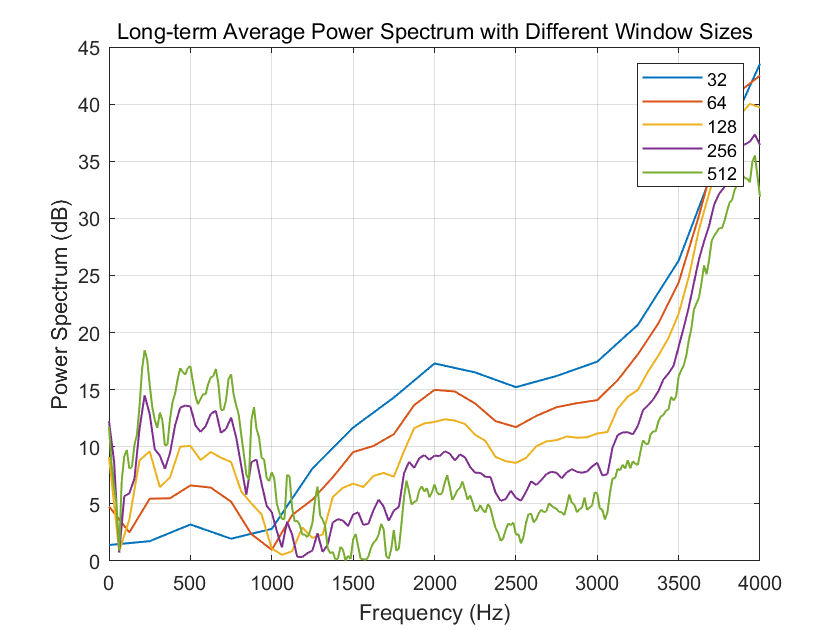


% power spectrum
[ps1_1, f1_1] = pspect(y1, fs1, 32, 32);
[ps1_2, f1_2] = pspect(y1, fs1, 64, 64);
[ps1_3, f1_3] = pspect(y1, fs1, 128, 128);
[ps1_4, f1_4] = pspect(y1, fs1, 256, 256);
[ps1_5, f1_5] = pspect(y1, fs1, 512, 512);

figure
plot(f1_1, abs(10*log10(ps1_1)), 'LineWidth', 1), hold on;
plot(f1_2, abs(10*log10(ps1_2)), 'LineWidth', 1), hold on;
plot(f1_3, abs(10*log10(ps1_3)), 'LineWidth', 1), hold on;
plot(f1_4, abs(10*log10(ps1_4)), 'LineWidth', 1), hold on;
plot(f1_5, abs(10*log10(ps1_5)), 'LineWidth', 1), hold off;
xlabel('Frequency (Hz)');
ylabel('Power Spectrum (dB)');
legend('32', '64', '128', '256', '512');
title('Long-term Average Power Spectrum with Different Window Sizes');
grid on;
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab9/P1_b.png", 'png')


% test on other wav file
win_len = 32

win_len = 32

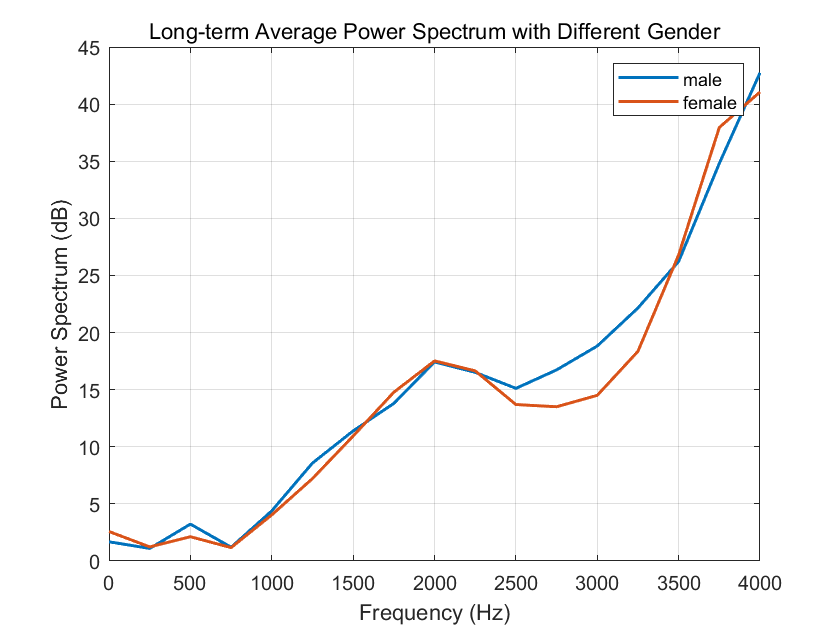

[p2, f2] = pspect(y2, fs2, win_len, win_len);
[p3, f3] = pspect(y3, fs3, win_len, win_len);
figure
plot(f2, abs(10*log10(p2)), 'LineWidth', 1.5), hold on;
plot(f3, abs(10*log10(p3)), 'LineWidth', 1.5), hold off;
xlabel('Frequency (Hz)');
ylabel('Power Spectrum (dB)');
legend('male', 'female');
title('Long-term Average Power Spectrum with Different Gender')
grid on;
saveas(gcf, "D:/作业提交/大三 下/语音信号处理/lab9/P1_c.png", 'png')